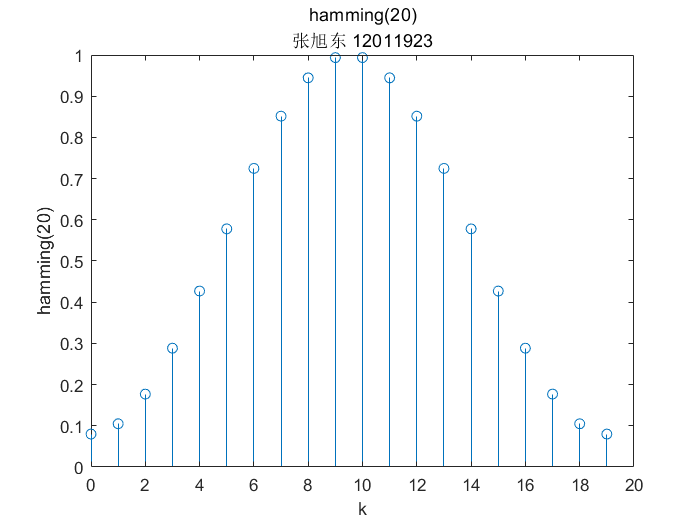

%5.2.1
x=hamming(20);
k=0:length(x)-1;
X=DFTsum(x);
figure;
stem(k,x);
xlabel('k');
ylabel('hamming(20)');
title(['hamming(20)' newline '张旭东 12011923']);

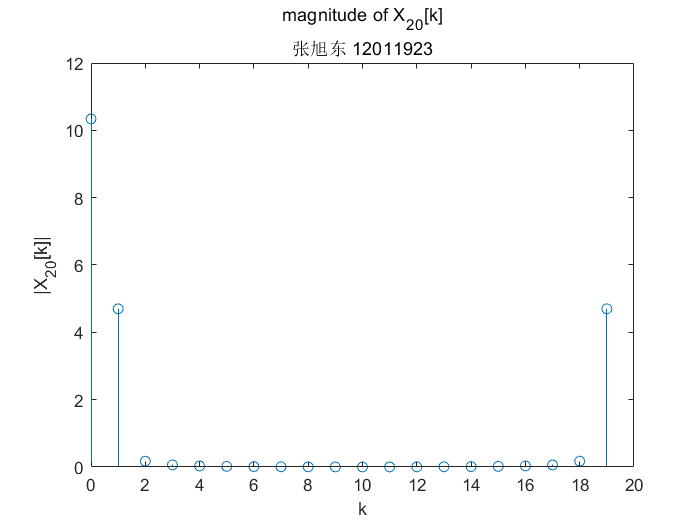

stem(k,abs(X));
xlabel('k');
ylabel('|X_2_0[k]|');
title(['magnitude of X_2_0[k]' newline '张旭东 12011923']);

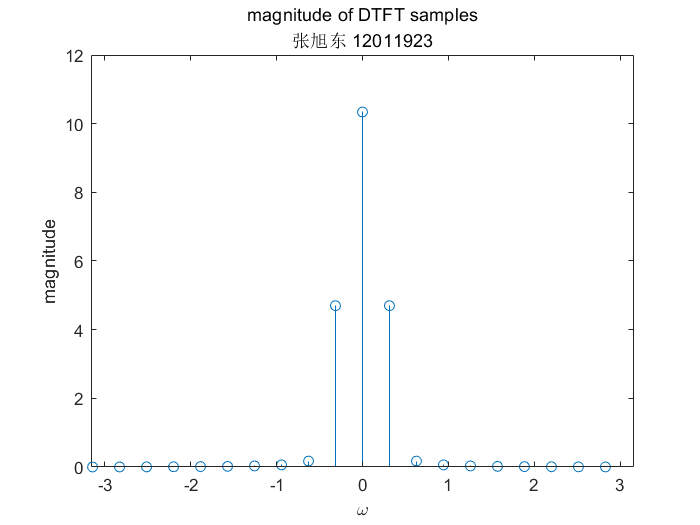


[X2,w2]=DTFTsamples(x);
stem(w2,abs(X2));
axis([-3.16 3.16 0 12]);
xlabel('\omega');
ylabel('magnitude');
title(['magnitude of DTFT samples' newline '张旭东 12011923']);

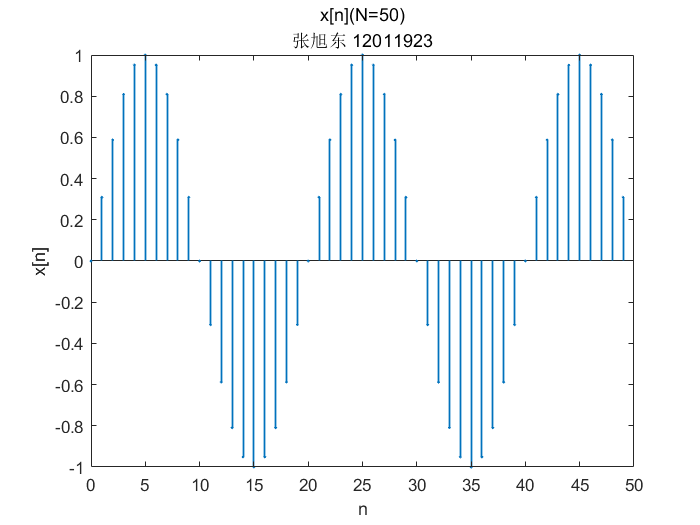


%5.2.2
N1=50;
n1=0:N1-1;
x1=sin(0.1*pi*n1);
[X1,w1]=DTFTsamples(x1);
stem(n1,x1,'linewidth',1,'Markersize',1);
xlabel('n');
ylabel('x[n]');
title(['x[n](N=50)' newline '张旭东 12011923']);

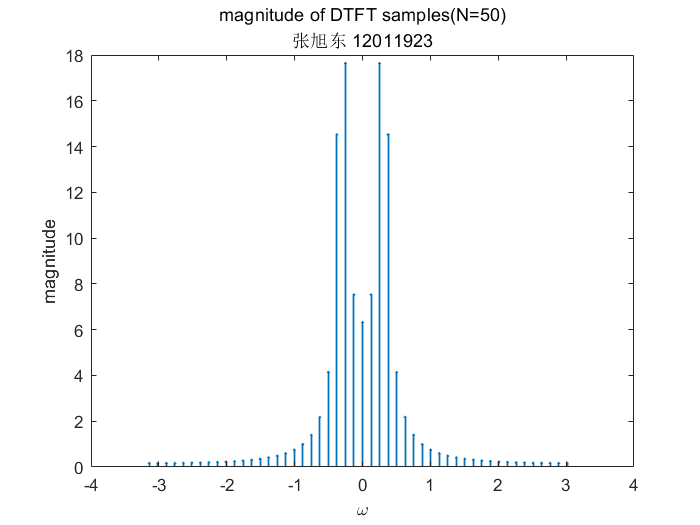

stem(w1,abs(X1),'linewidth',1,'Markersize',1);
xlabel('\omega');
ylabel('magnitude');
title(['magnitude of DTFT samples(N=50)' newline '张旭东 12011923']);

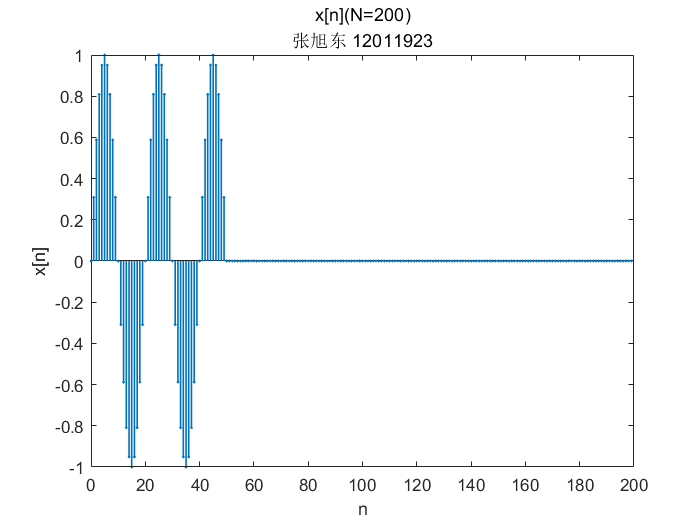


N3=200;
n3=0:N3-1;
x3=[x1 zeros(1,150)];
[X3,w3]=DTFTsamples(x3);
stem(n3,x3,'linewidth',1,'Markersize',1);
xlabel('n');
ylabel('x[n]');
title(['x[n](N=200)' newline '张旭东 12011923']);

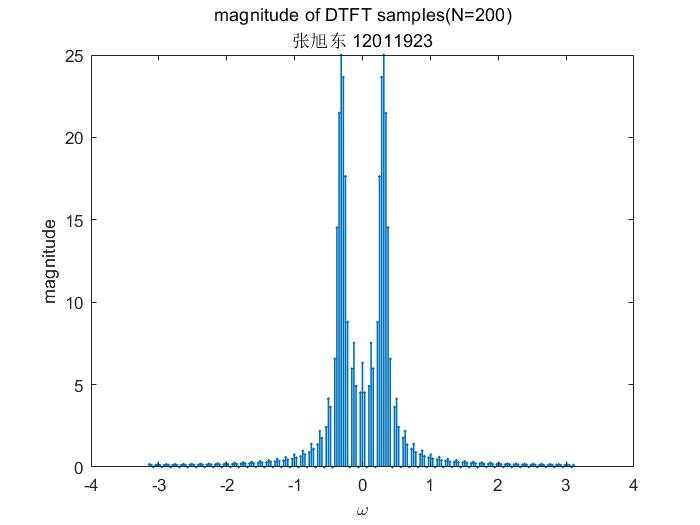

stem(w3,abs(X3),'linewidth',1,'Markersize',1);
xlabel('\omega');
ylabel('magnitude');
title(['magnitude of DTFT samples(N=200)' newline '张旭东 12011923']);